%% Variables
syms q1 q2 q3% DOF
syms q1dot q2dot q3dot%
syms q1ddot q2ddot q3ddot%

q = [q1; q2; q3];
qdot = [q1dot; q2dot; q3dot];
qddot = [q1ddot; q2ddot; q3ddot];

% DOF wrt t
syms qt1(t) qt2(t) qt3(t)

qt(t) = [qt1; qt2; qt3];
qtdot(t) = diff(qt,1);
qtddot(t) = diff(qt, 2);

%Gravity
g = [0,9.81];

%Link Lengths
L1 = 1;
L2 = 1;
L3 = 1;


%Masses
density = 1;
Area = 1;
M1 = L1*density*Area;
M2 = L2*density*Area;
M3 = L3*density*Area;

M = [M1, M2, M3];

%Inertias
I1 = 1/12*M1*L1;
I2 = 1/12*M2*L2;
I3 = 1/12*M3*L3;

I = [I1, I2, I3];

%Theta
Th1 = q1;
Th2 = q1 + q2;
Th3 = q1 + q2 + q3;

%% Dynamics
%Relative Joint Direction (Unit Vector)
JD0 = [cos(Th1) sin(Th1)];
JD1 = [cos(Th2) sin(Th2)];
JD2 = [cos(Th3) sin(Th3)];

%Relative End Posistions
OE1 = L1*[cos(Th1) sin(Th1)];
E1E2 = L2*[cos(Th2) sin(Th2)];
E2E3 = L3*[cos(Th3) sin(Th3)];

%End Positions
O = [0 0];
E1 = O + OE1;
E2 = E1 + E1E2;
E3 = E2 + E2E3;

%Centroid Positions
C1 = O + .5*OE1;
C2 = E1 + .5*E1E2;
C3 = E2 + .5*E2E3;
C = [C1; C2; C3];

CM = COM(C,M)

$$CM = \left(\begin{array}{cc} \frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{6}+\frac{\cos\left(q_{1}+q_{2}\right)}{2}+\frac{5\,\cos\left(q_{1}\right)}{6} & \frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{6}+\frac{\sin\left(q_{1}+q_{2}\right)}{2}+\frac{5\,\sin\left(q_{1}\right)}{6} \end{array}\right)$$

syms h_cm
const=CM==[0 h_cm]

$$const = \left(\begin{array}{cc} \frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{6}+\frac{\cos\left(q_{1}+q_{2}\right)}{2}+\frac{5\,\cos\left(q_{1}\right)}{6}=0 & \frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{6}+\frac{\sin\left(q_{1}+q_{2}\right)}{2}+\frac{5\,\sin\left(q_{1}\right)}{6}=h_{\mathrm{cm}} \end{array}\right)$$

assume(h_cm>0)
assume(-pi<q2<pi)
assume(-pi<q3<pi)
assume(0<q1<pi)
sol=solve(const(1),[q1],'ReturnConditions',true,'Real',true,'IgnoreAnalyticConstraints', true)

sol = struct with fields:
            q1: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


sol.q1

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{3\,\sin\left(q_{2}\right)+\sigma_{4}+\sigma_{3}-\sigma_{1}}{\sigma_{2}}\right)\\ -2\,\mathrm{atan}\left(\frac{3\,\sin\left(q_{2}\right)+\sigma_{4}+\sigma_{3}+\sigma_{1}}{\sigma_{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\cos\left(q_{2}\right)}^{2}\,{\cos\left(q_{3}\right)}^{2}+6\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)+{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{3}\right)}^{2}+9\,{\cos\left(q_{2}\right)}^{2}+10\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+30\,\cos\left(q_{2}\right)+{\cos\left(q_{3}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}+6\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}+{\sin\left(q_{2}\right)}^{2}\,{\sin\left(q_{3}\right)}^{2}+9\,{\sin\left(q_{2}\right)}^{2}-10\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+25}\\ \sigma_{2}=3\,\cos\left(q_{2}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+5\\ \sigma_{3}=\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}$$

sol.parameters

 
ans =
 
Empty sym: 1-by-0
 


sol.conditions

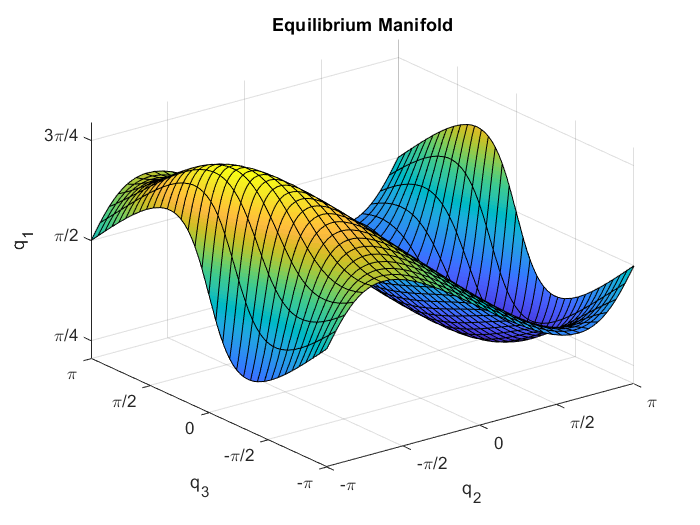


fsurf(sol.q1(1),[-pi pi -pi pi])
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([pi/4 pi/2 3*pi/4])
zticklabels({'\pi/4','\pi/2','3\pi/4'})
zlabel('q_1')
xlabel('q_2')
ylabel('q_3')
title('Equilibrium Manifold')

%plot3(simout.Data(:,2),simout.Data(:,3),simout.Data(:,1),'k')
hold off

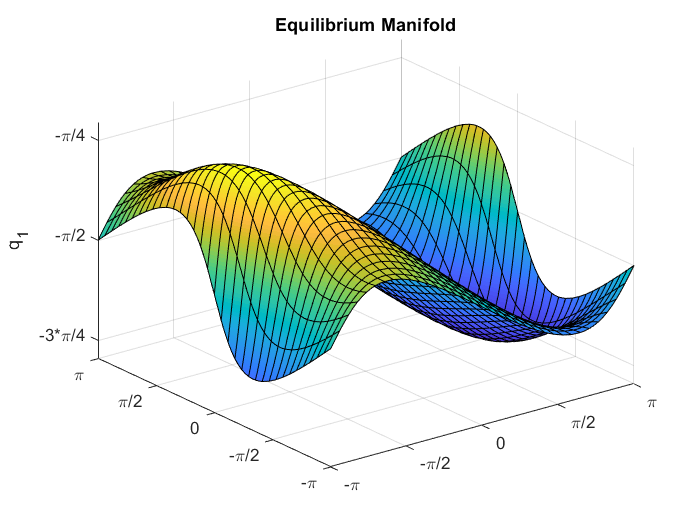


fsurf(sol.q1(2),[-pi pi -pi pi])
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([-3*pi/4 -pi/2 -pi/4])
zticklabels({'-3*\pi/4','-\pi/2','-\pi/4'})
zlabel('q_1')
title('Equilibrium Manifold')
hold off


q_2=-pi:pi/30:pi;
q_3=-pi:pi/30:pi;

qcont1 = zeros(length(q_2));
qcont2 = zeros(length(q_2));
q1func = matlabFunction(sol.q1(1));
Efunc = matlabFunction([E1(2);E2(2);E3(2)]);
condfunc1 = matlabFunction(sol.conditions(1));
condfunc2 = matlabFunction(sol.conditions(2));
for i=1:length(q_2)
    for j=1:length(q_3)
        if isAlways(condfunc1(q_2(i),q_3(j)))
            q_1 = q1func(q_2(i),q_3(j));
            E = isAlways(Efunc(q_1,q_2(i),q_3(j))>=[0;0;0]);
            if E
            qcont1(i,j) = q_1;
            end
        end
        if isAlways(condfunc2(q_2(i),q_3(j)))
            qcont2(i,j) = 1;
        end
    end
end
        

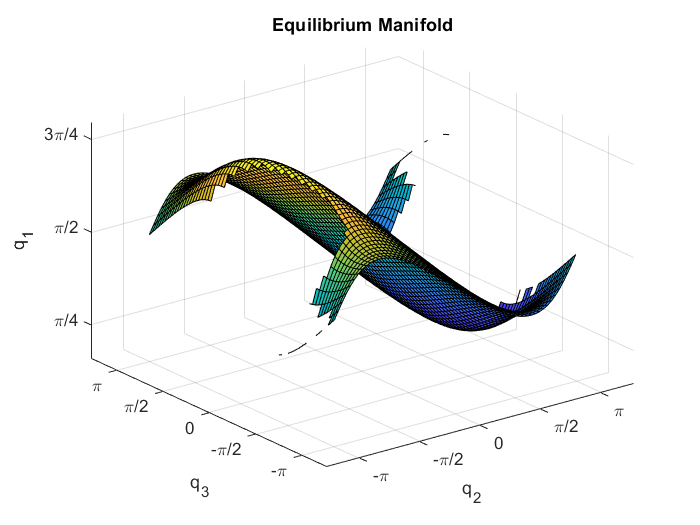

qcont1(qcont1 == 0) = NaN;
surf(q_2,q_3,qcont1.')
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([pi/4 pi/2 3*pi/4])
zticklabels({'\pi/4','\pi/2','3\pi/4'})
zlabel('q_1')
xlabel('q_2')
ylabel('q_3')
title('Equilibrium Manifold')
hold off

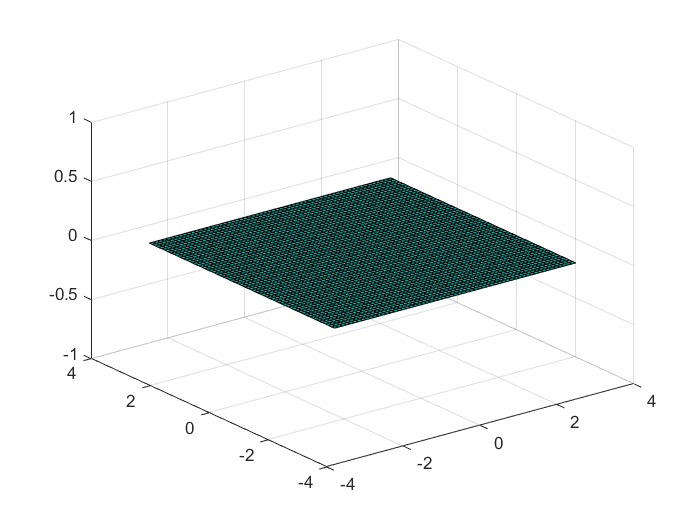

surf(q_2,q_3,qcont2)

epsilon = -pi/2:pi/50:pi/2+pi/50;
q_2=-pi:pi/100:pi+pi/100;
q_3=-pi:pi/100:pi+pi/100;
q_1func = matlabFunction(sol.q1(1));
q_1=zeros(length(q_2),length(q_3));

DC = zeros(length(q_2),length(q_3),length(epsilon));
rank_C = zeros(length(q_2),length(q_3),length(epsilon));
for i=1:length(q_2)
    for j=1:length(q_3)
        for k=1:length(epsilon)
            q_1(i,j) = q_1func(q_2(i),q_3(j));
            Cont = ContWOTorque(q_1(i,j)+epsilon(k),q_2(i),q_3(j),0,0,0);
            Cont66_ = Cont*Cont.';
            DC(i,j,k) = log(det(Cont66_));
            rank_C(i,j,k) = rank(Cont66_);
        end
    end
end


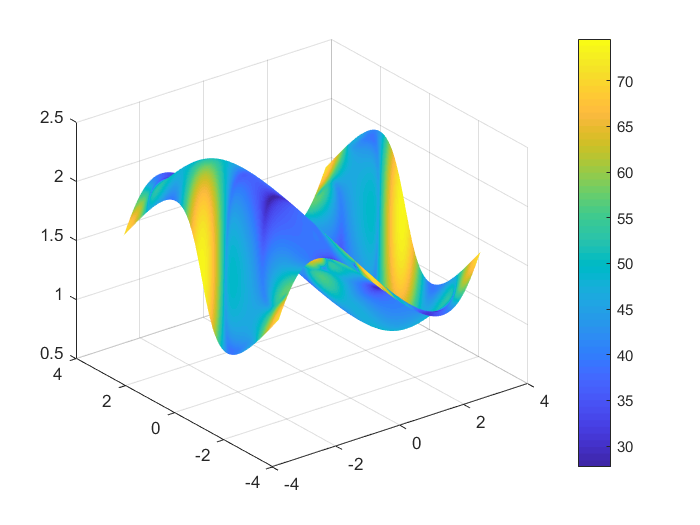


surf(q_2,q_3,q_1.'+epsilon(26),real(DC(:,:,26)).','EdgeColor','none','FaceColor','interp')
colorbar;

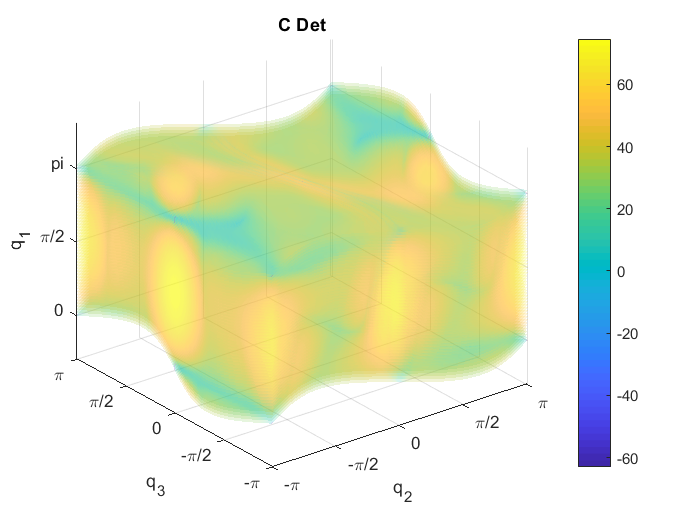

surf(q_2,q_3,q_1.'+epsilon(26),real(DC(:,:,26)).','FaceAlpha',0.2,'EdgeColor','none','FaceColor','interp')

hold on
for i=1:length(epsilon)
    surf(q_2,q_3,q_1.'+epsilon(i),real(DC(:,:,i)).','FaceAlpha',0.2,'EdgeColor','none')
end
axis tight;
colorbar
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
xticks([-pi -pi/2 0 pi/2  pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([0 pi/2 pi])
zticklabels({'0','\pi/2','pi'})
xlabel('q_2')
ylabel('q_3')
zlabel('q_1')
title('C Det')
hold off

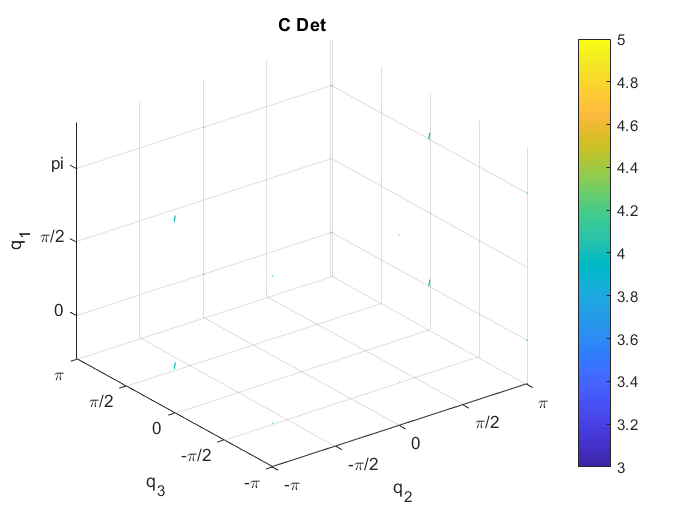

rank_C(rank_C == 6) = NaN;
surf(q_2,q_3,q_1.'+epsilon(26),rank_C(:,:,26).','FaceAlpha',1,'EdgeColor','none')
hold on
for i=1:length(epsilon)
    surf(q_2,q_3,q_1.'+epsilon(i),rank_C(:,:,i).','FaceAlpha',1,'EdgeColor','none')
end
axis tight;
colorbar
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
xticks([-pi -pi/2 0 pi/2  pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([0 pi/2 pi])
zticklabels({'0','\pi/2','pi'})
xlabel('q_2')
ylabel('q_3')
zlabel('q_1')
title('C Det')
hold off

jack = jacobian(sol.q1(1),[q2;q3])

$$jack = \begin{array}{l} \left(\begin{array}{cc} -\frac{2\,\left(\frac{3\,\cos\left(q_{2}\right)+\sigma_{9}-\sigma_{8}+\frac{30\,\sin\left(q_{2}\right)+10\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\sigma_{1}}{2\,\sigma_{5}}}{\sigma_{4}}+\frac{\left(3\,\sin\left(q_{2}\right)+\sigma_{7}+\sigma_{6}\right)\,\sigma_{3}}{{\sigma_{4}}^{2}}\right)}{\sigma_{2}} & -\frac{2\,\left(\frac{\sigma_{9}-\sigma_{8}+\frac{6\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}+10\,\sin\left(q_{3}\right)\,\cos\left(q_{2}\right)+6\,\sin\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}+\sigma_{1}}{2\,\sigma_{5}}}{\sigma_{4}}+\frac{\left(\sigma_{7}+\sigma_{6}\right)\,\sigma_{3}}{{\sigma_{4}}^{2}}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=10\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\frac{{\sigma_{3}}^{2}}{{\sigma_{4}}^{2}}+1\\ \sigma_{3}=3\,\sin\left(q_{2}\right)+\sigma_{7}+\sigma_{6}-\sigma_{5}\\ \sigma_{4}=3\,\cos\left(q_{2}\right)+\sigma_{9}-\sigma_{8}+5\\ \sigma_{5}=\sqrt{{\cos\left(q_{2}\right)}^{2}\,{\cos\left(q_{3}\right)}^{2}+6\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)+{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{3}\right)}^{2}+9\,{\cos\left(q_{2}\right)}^{2}+10\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+30\,\cos\left(q_{2}\right)+{\cos\left(q_{3}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}+6\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}+{\sin\left(q_{2}\right)}^{2}\,{\sin\left(q_{3}\right)}^{2}+9\,{\sin\left(q_{2}\right)}^{2}-10\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+25}\\ \sigma_{6}=\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{7}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{8}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{9}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) \end{array}$$

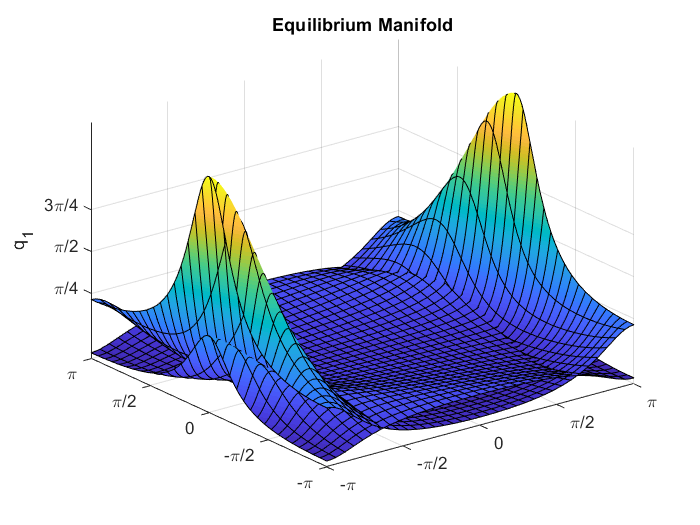

fsurf(jack,[-pi pi -pi pi])
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zticks([pi/4 pi/2 3*pi/4])
zticklabels({'\pi/4','\pi/2','3\pi/4'})
zlabel('q_1')
title('Equilibrium Manifold')

%plot3(simout.Data(:,2),simout.Data(:,3),simout.Data(:,1),'k')
hold off

diffsolq1 = diff(subs(sol.q1(1),[q2,q3],[qt2,qt3]),1);
diffsolq1 = subs(diffsolq1,[qt;qtdot],[q;qdot])

torque = simplify(ridgid_torque([q(1:3);qdot(1:3)]))

VFt = (threedof_ground(-torque(1),-torque(2),[q(1:3);qdot(1:3)]));
VFt = subs(VFt,[q1;qdot],[sol.q1(1);0;0;0]);
VFtfunc = matlabFunction(sqrt(VFt.'*VFt))

VFtfunc = function_handle with value:
    @(q2,q3)sqrt(1.0./(cos(q2.*2.0).*8.1e1+cos(q3.*2.0).*4.5e1-cos(q2.*2.0+q3.*2.0).*9.0-1.69e2).^2.*(cos(q2-q3+atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+cos(q2).*cos(q3).*1.0e1-sin(q2).*sin(q3).*1.0e1+cos(q2).^2.*9.0+sin(q2).^2.*9.0+cos(q2).^2.*cos(q3).*6.0+cos(q3).*sin(q2).^2.*6.0+cos(q2).^2.*cos(q3).^2+cos(q2).^2.*sin(q3).^2+cos(q3).^2.*sin(q2).^2+sin(q2).^2.*sin(q3).^2+2.5e1))./(cos(q2).*3.0+cos(q2).*cos(q3)-sin(q2).*sin(q3)+5.0)).*2.0).*(-1.32435e4)+cos(-q2+q3+atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+cos(q2).*cos(q3).*1.0e1-sin(q2).*sin(q3).*1.0e1+cos(q2).^2.*9.0+sin(q2).^2.*9.0+cos(q2).^2.*cos(q3).*6.0+cos(q3).*sin(q2).^2.*6.0+cos(q2).^2.*cos(q3).^2+cos(q2).^2.*sin(q3).^2+cos(q3).^2.*sin(q2).^2+sin(q2).^2.*sin(q3).^2+2.5e1))./(cos(q2).*3.0+cos(q2).*cos(q3)-sin(q2).*sin(q3)+5.0)).*2.0).*8.829e3-cos(q2+q3.*2.0-atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+

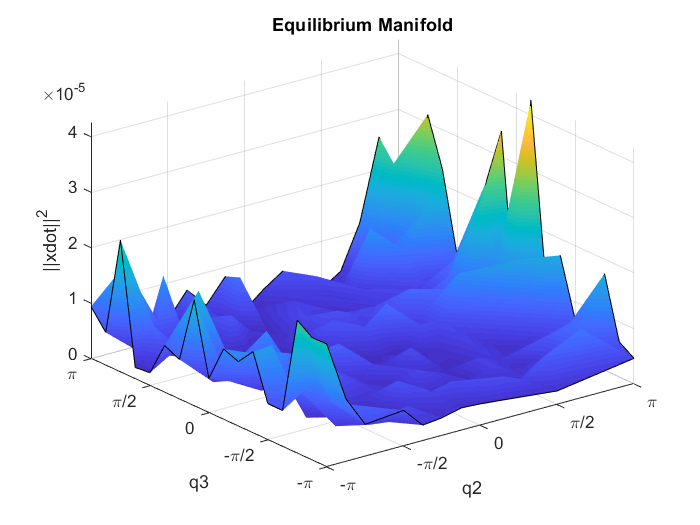

fsurf(VFtfunc,[-pi pi -pi pi],'MeshDensity',2)
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zlabel('||xdot||^2')
xlabel('q2')
ylabel('q3')
title('Equilibrium Manifold')
hold off

CM_23 = [COM(C(2:3,:),M(2:3))];
tau = [(CM_23(1)-OE1(1))*(9.81)*(sum(M(2:3)));
    (C(3,1)-(OE1(1) + E1E2(1)))*(9.81)*(sum(M(3)))]

$$tau = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{200}+\frac{2943\,\cos\left(q_{1}+q_{2}\right)}{200}\\ \frac{981\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{200} \end{array}\right)$$


VFtau = (threedof_ground(-tau(1),-tau(2),[q(1:3);qdot(1:3)]));
VFtau = subs(VFtau,[q1;qdot],[sol.q1(1);0;0;0]);
VFtaufunc = matlabFunction(sqrt(VFtau.'*VFtau))

VFtaufunc = function_handle with value:
    @(q2,q3)sqrt(1.0./(cos(q2.*2.0).*8.1e1+cos(q3.*2.0).*4.5e1-cos(q2.*2.0+q3.*2.0).*9.0-1.69e2).^2.*(cos(q2-atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+cos(q2).*cos(q3).*1.0e1-sin(q2).*sin(q3).*1.0e1+cos(q2).^2.*9.0+sin(q2).^2.*9.0+cos(q2).^2.*cos(q3).*6.0+cos(q3).*sin(q2).^2.*6.0+cos(q2).^2.*cos(q3).^2+cos(q2).^2.*sin(q3).^2+cos(q3).^2.*sin(q2).^2+sin(q2).^2.*sin(q3).^2+2.5e1))./(cos(q2).*3.0+cos(q2).*cos(q3)-sin(q2).*sin(q3)+5.0)).*2.0).*3.38445e4+cos(atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+cos(q2).*cos(q3).*1.0e1-sin(q2).*sin(q3).*1.0e1+cos(q2).^2.*9.0+sin(q2).^2.*9.0+cos(q2).^2.*cos(q3).*6.0+cos(q3).*sin(q2).^2.*6.0+cos(q2).^2.*cos(q3).^2+cos(q2).^2.*sin(q3).^2+cos(q3).^2.*sin(q2).^2+sin(q2).^2.*sin(q3).^2+2.5e1))./(cos(q2).*3.0+cos(q2).*cos(q3)-sin(q2).*sin(q3)+5.0)).*2.0).*3.1392e4+cos(q2.*2.0+q3.*2.0-atan((sin(q2).*3.0+cos(q2).*sin(q3)+cos(q3).*sin(q2)-sqrt(cos(q2).*3.0e1+cos(q

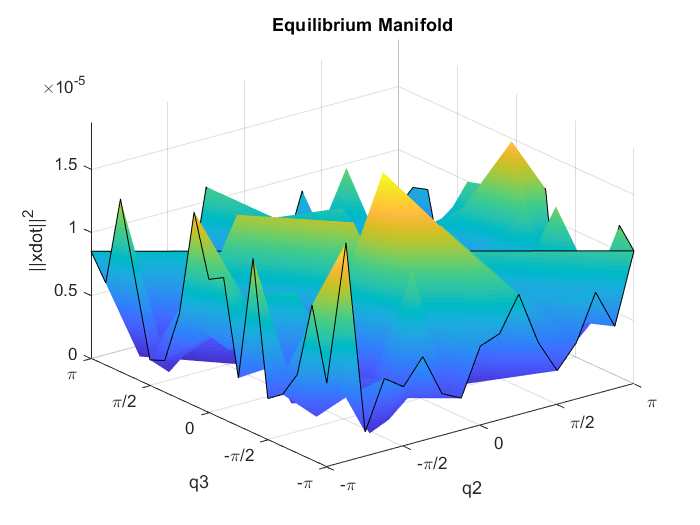

fsurf(VFtaufunc,[-pi pi -pi pi],'MeshDensity',2)
hold on
xticks([-pi -pi/2 0 pi/2 pi])
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
yticks([-pi -pi/2 0 pi/2  pi])
yticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})
zlabel('||xdot||^2')
xlabel('q2')
ylabel('q3')
title('Equilibrium Manifold')
hold off